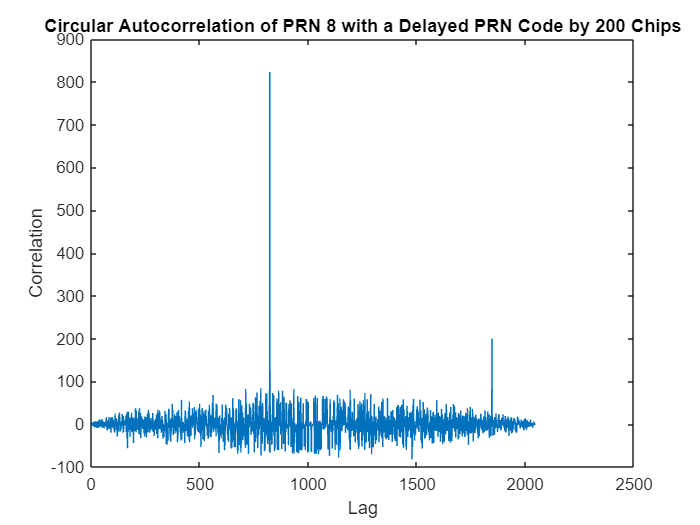

% Q1
% Generate a PRN 8 code
prn8 = generateCAcode(8);
% Delay the PRN code by 200 chips
delayed_prn8 = circshift(prn8, 200);
circular_autocorrelation = xcorr( prn8, delayed_prn8);
figure;
plot(circular_autocorrelation);
xlabel('Lag');
ylabel('Correlation');
title('Circular Autocorrelation of PRN 8 with a Delayed PRN Code by 200 Chips');

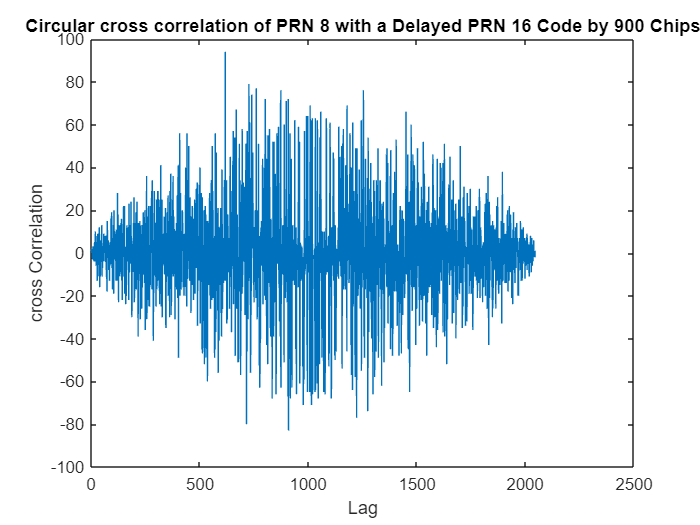

%Q2
% PRN 16 code generation  bn
prn16 = generateCAcode(16);
delayed_prn16 = circshift(prn16, 900);
circular_cross_corr = xcorr(prn8, delayed_prn16);
figure;
plot(circular_cross_corr);
xlabel('Lag');
ylabel('cross Correlation');
title('Circular cross correlation of PRN 8 with a Delayed PRN 16 Code by 900 Chips');

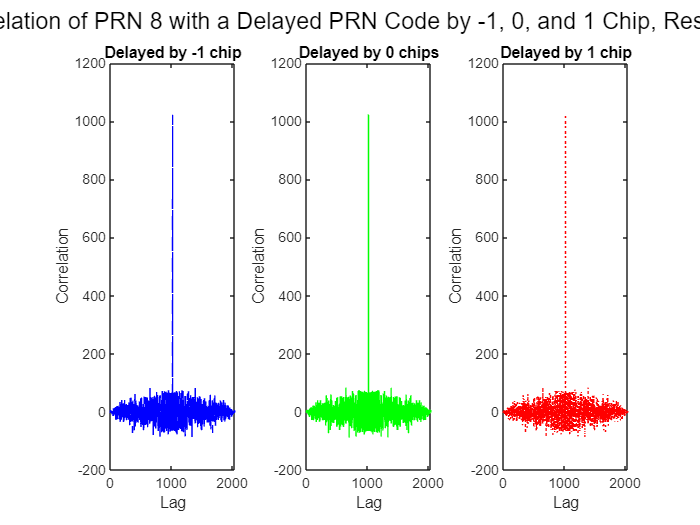

%Q3
% Generate a PRN 8 code
prn8 = generateCAcode(8);

% Delay the PRN code by -1, 0, and 1 chip
delayed_prn8_neg_one = circshift(prn8, -1);
delayed_prn8_zero = prn8;
delayed_prn8_pos_one = circshift(prn8, 1);

% Compute the autocorrelation
autocorrelation_neg_one = xcorr(prn8, delayed_prn8_neg_one);
autocorrelation_zero = xcorr(prn8, delayed_prn8_zero);
autocorrelation_pos_one = xcorr(prn8, delayed_prn8_pos_one);

% Plot the autocorrelation
figure;
subplot(1,3,1);
plot(autocorrelation_neg_one, 'b--');
xlabel('Lag');
ylabel('Correlation');
title('Delayed by -1 chip');

subplot(1,3,2);
plot(autocorrelation_zero, 'g-');
xlabel('Lag');
ylabel('Correlation');
title('Delayed by 0 chips');

subplot(1,3,3);
plot(autocorrelation_pos_one, 'r:');
xlabel('Lag');
ylabel('Correlation');
title('Delayed by 1 chip');

sgtitle('Autocorrelation of PRN 8 with a Delayed PRN Code by -1, 0, and 1 Chip, Respectively');

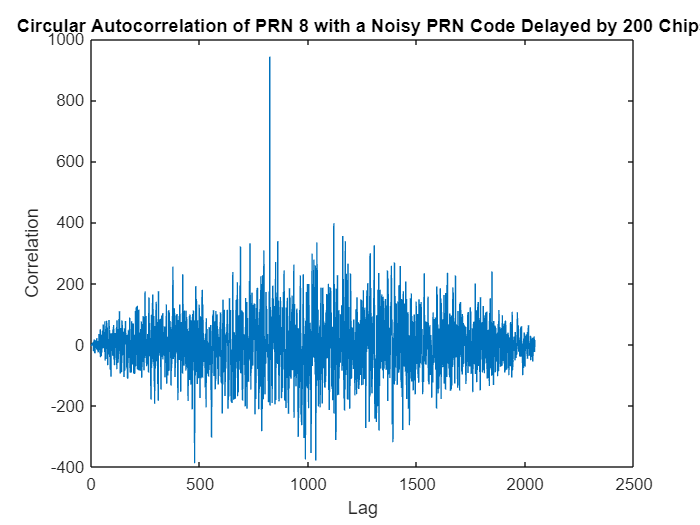

%Q4
% Generate a PRN 8 code
prn8 = generateCAcode(8);

% Generate a noisy PRN code delayed by 200 chips
delayed_prn8 = circshift(prn8, 200);

% Normal dist. with size of transpose(prn8) delayed by 200 chips
a = randn(length(delayed_prn8), 1) * 4 + 0; % this is vector (size = 1023x1)

% noise 
b = a.';   % Transpose of a to make size = 1x1023

noisy_delayed_prn8 = delayed_prn8 + b;

% Compute the circular autocorrelation
circular_autocorrelation = xcorr(prn8, noisy_delayed_prn8);

% Plot the circular autocorrelation
figure;
plot(circular_autocorrelation);
xlabel('Lag');
ylabel('Correlation');
title('Circular Autocorrelation of PRN 8 with a Noisy PRN Code Delayed by 200 Chips');